x_1 = 1;
h = 1;
n = 10;
x = x_1:h:(x_1+(n-1)*h);
t = x_1:0.1:x(n);
f = sin(x);
hold on;

- Полином Лагранжа

L = Lagranzh(n,x,f);
plot(t,polyval(L,t),"ro")

- Полином Ньютона

N = Newton(n,h,x,f);
plot(t,polyval(N,t),"b*")

- Полином Чебышёва

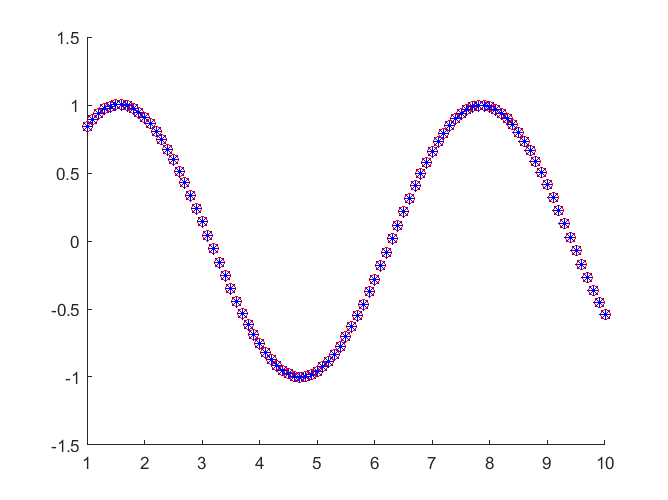

hold off;

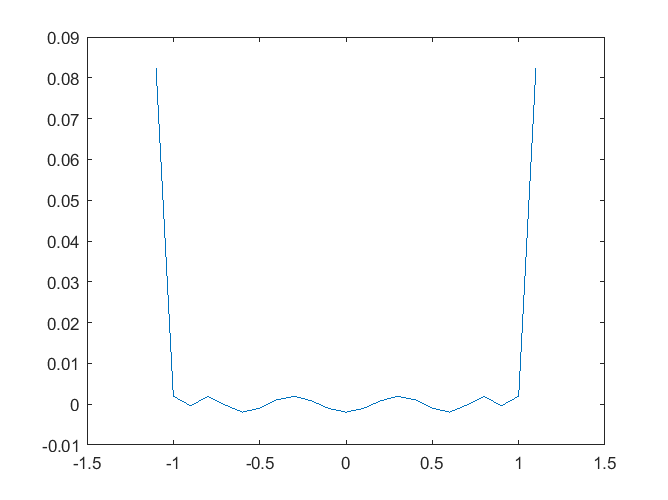

T = Chebyshev(n);
t = -1.1:0.1:1.1;
plot(t,polyval(T,t));

coef = ((n-1)*h)/2;
sized_x = roots(T);
for i = 1:n
    sized_x(i) = (sized_x(i)+1)*coef+x_1;
end

- Сравнение приближения

max_otkl_1 = 0;
max_x_1 = 0;
for i = x_1:0.001:(x_1+(n-1)*h)
    if (abs(sin(i)-polyval(N,i)))>max_otkl_1
        max_otkl_1 = abs(sin(i)-polyval(N,i));
        max_x_1 = i;
    end
end
y_corr_1 = sin(max_x_1);
y_wr_1 = polyval(N,max_x_1);

max_otkl_2 = 0;
max_x_2 = 0;
sized_y = sin(sized_x);
L = Lagranzh(n,sized_x,sized_y);
for i = x_1:0.001:(x_1+(n-1)*h)
    if (abs(sin(i)-polyval(L,i)))>max_otkl_2
        max_otkl_2 = abs(sin(i)-polyval(L,i));
        max_x_2 = i;
    end
end
y_corr_2 = sin(max_x_2);
y_wr_2 = polyval(L,max_x_2);

max_x_1

max_x_1 = 1.2920

max_otkl_1

max_otkl_1 = 0.0075

max_x_2

max_x_2 = 1

max_otkl_2

max_otkl_2 = 0.0011

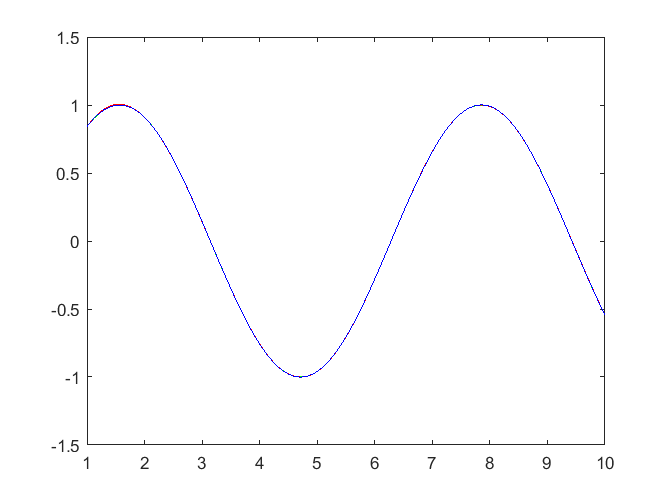

t = x_1:0.001:(x_1+(n-1)*h);
plot(t,sin(t),"green",t,polyval(N,t),"r",t, polyval(L,t),"b")
line([max_x_1,max_x_1],[y_corr_1,y_wr_1],'color','blue')
line([max_x_2,max_x_2],[y_corr_2,y_wr_2],'color','red')

- Динамика

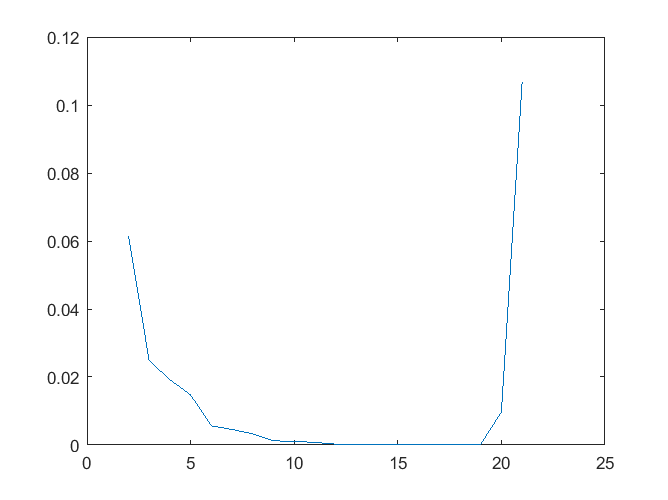

max_otkl_Cheb = 0;
for n = 2:1:21
    x = roots(Chebyshev(n));
    for i = 1:n
        x(i) = (x(i)+1)*((n-1)*h/2)+x_1;
    end
    y = sin(x);
    L = Lagranzh(n,x,y);
    if (n ~= 2)
        max_otkl_Cheb = conv(max_otkl_Cheb,[0,1]);
    end
    p = x_1:0.001:(x_1+(n-1)*h);
    max_otkl_Cheb(1) = max(abs(sin(p)-polyval(L,p)));
end
n = 21:-1:2;
plot(n,max_otkl_Cheb);